# **ECE 1473 OFDM Tutorial: **

# **Modulate Message Using OFDM with Cyclic Prefixing**

## **Author: Adam Nichols**

clear, clc

## Introduction:

    In this section, multiple symbols of OFDM will be combined together in the same transmission to send an entire message. In the previous section, single symbols of OFDM were generated. Now, to send a user's message with any reasonable length, multiple symbols must be encoded to form a physical layer packet. Some challenges arise when combining symbols using a rectangular window, which can be resolved using cyclic prefixing.

## Message Generation:

    First, a message of random bits will be generated to simulate a user transmitting a signal over the channel. For simplicity, this simulation will assume that the user message fills all OFDM symbols in the message. The user's message will be parallelized into a number of bitstreams equivalent to the number of carriers. See the diagram below to see how the user serial bitstream is parallelized into OFDM symbols and parallel bitstreams.

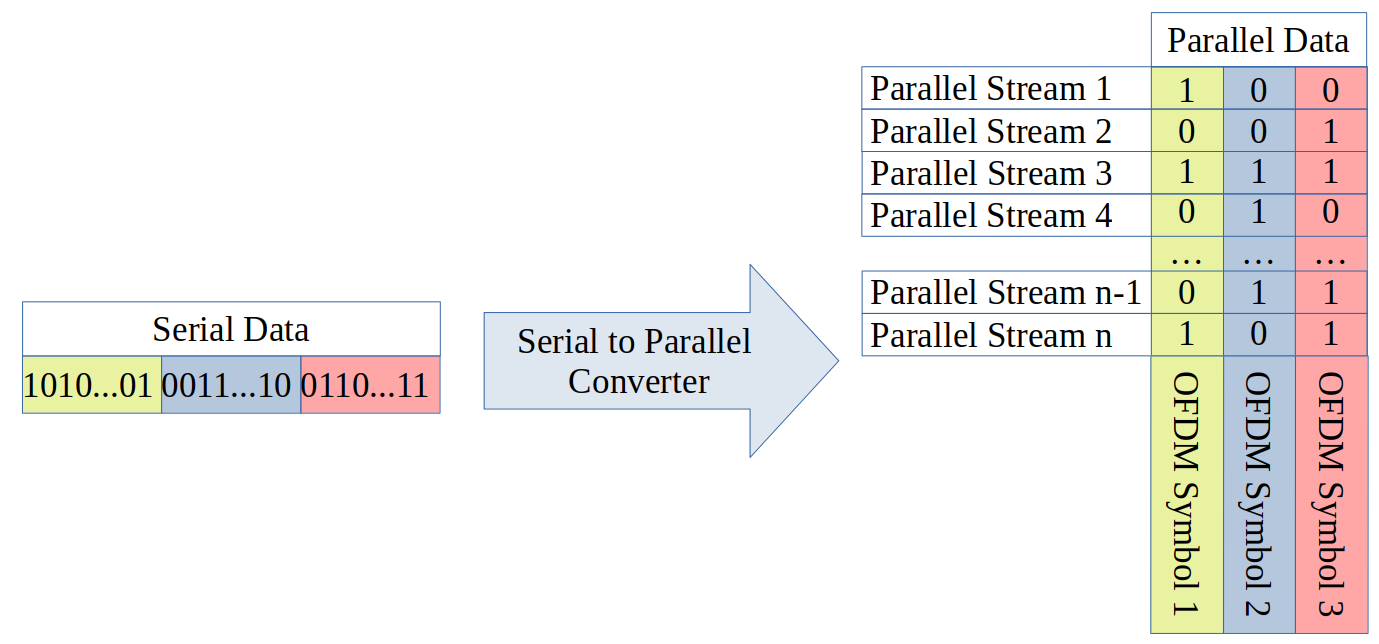

    Pick the number of carriers (number of parallel bitstreams) for the OFDM symbol from the dropdown menu below. Then, pick the number of bits (in multiples of the number of carriers), and the number will be displayed below the dropdown. The bits being sent on the channel will be displayed as a row vector below. After this, the reshape function parallelizes the bits into OFDM symbols.

num_carriers = 8;
num_symbols = 3

num_symbols = 3

num_bits = num_carriers * num_symbols;
bits = RandomBits(num_bits);
transpose(bits)

ans =      0     1     0     1     1     1     0     0     0     1     0     1     0     0     0     0     1     1     1     0     1     1     0     1


data = reshape(bits,num_carriers,[])

data =      0     0     1
     1     1     1
     0     0     1
     1     1     0
     1     0     1
     1     0     1
     0     0     0
     0     0     1


## OFDM Modulation:

    Next, the user bits are modulated into OFDM symbols in the same way as the previous section. The user bits are converted into antipodal values and the IFFT is perfomed to create the baseband signal. 

    Now, all the symbols will be concatenated with a rectangular window. This is a very simple method to 

fourier_coeffs = data*2 - 1;
s_mod = zeros(num_carriers,num_symbols);
for i = 0:num_symbols-1
    s_mod(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

    Now, the timing and frequency domain parameters of the OFDM signal are defined. First, the bandwidth of the OFDM message 

bandwidth = 10000;

    Next, the sample rate and the sample times are defined. Recall that the sample rate for modulating OFDM is the bandwidth. Also, as an FYI the symbol time and symbol rate are calculated below. These values represent how long a single symbol of OFDM takes to transmit and how many symbols of OFDM are sent per second.

fs = bandwidth;
ts = 1/fs;
t = transpose((0:num_carriers*num_symbols-1)*ts);

symboltime = ts * num_carriers;
fprintf("Symbol Time: "); fprintf(num2str(symboltime)); fprintf(" [sec]")

Symbol Time: 0.0008 [sec]

symbolrate = 1/symboltime;
fprintf("Symbol Rate: "); fprintf(num2str(symbolrate)); fprintf(" [baud]")

Symbol Rate: 1250 [baud]

    After this, upsampling is performed to get a better representation of the baseband analog signal and out-of-band effects. A default upsampling value of 4 is chosen, but feel free to use the dropdown to change the upsampling ratio. The new sample rate and sample times are calculated for the upsampled signal.

upsamp = 4;
fs_upsamp = upsamp*fs;
ts_upsamp = ts/upsamp;

    Upsampling with sinc interpolation is done in the same method as in the previous section. This outputs a higher sample rate signal and each symbol is periodic.

s_upsamp = zeros(num_carriers*upsamp,num_symbols);
for i = 0:num_symbols-1
    s_curr = s_mod(i*num_carriers+1:(i+1)*num_carriers);
    if num_symbols > 1
        s_curr = transpose(s_curr);
    end
    s_curr_triple = [s_curr; s_curr; s_curr];
    s_curr_triple_upsamp = resample(s_curr_triple,upsamp,1);
    s_curr_upsamp = s_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);
    s_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_curr_upsamp;
end

    Next, all the symbols will be concatenated together. Rectangular windowing is used, which means that the symbols will all be right next to each other. When switching to the next symbol, a jump discontinuity will be present, which causes high frequency (out-of-band) emissions. Recall that the shape of the Fourier transform of the rectangular pulse has a sinc shape in the frequency domain. These spurious emissions from the jump discontinuities will not comply with wireless channel requirements from the FCC. We will see this result when doing spectral analysis in a next step.

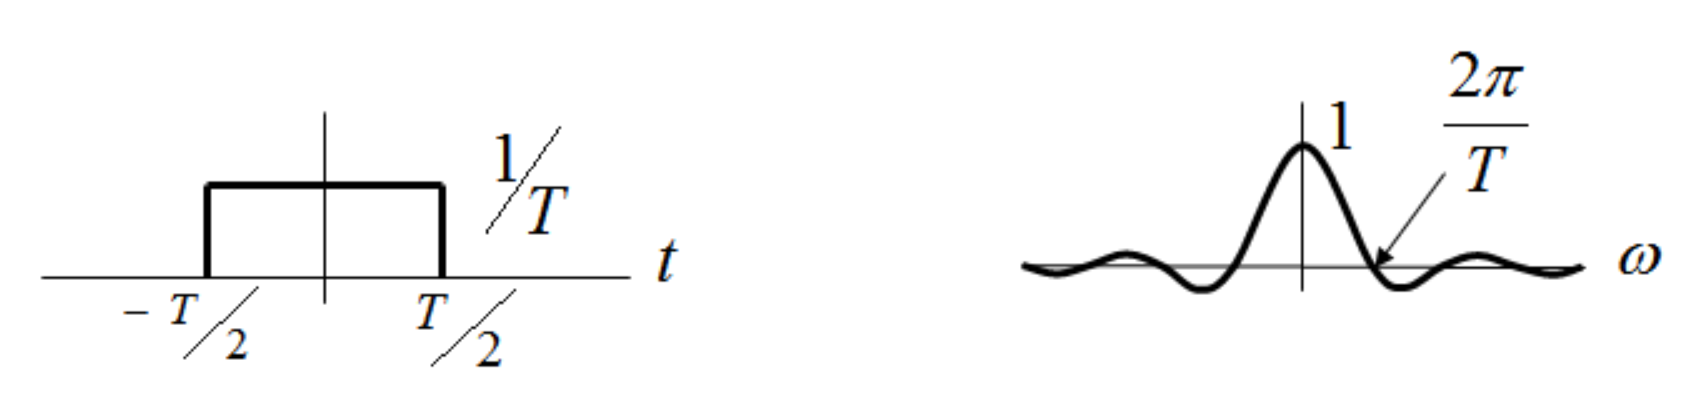

[1] Fourier transform pair of rectangular pulse and sinc function.

s_upsamp_vec = reshape(s_upsamp,[],1);

    Then, the message is zero-padded. This is useful when using filters on the message in a later step. Then, the time vector is generated for the upsampled and zero-padded message. See the figure below for a visual representation of the

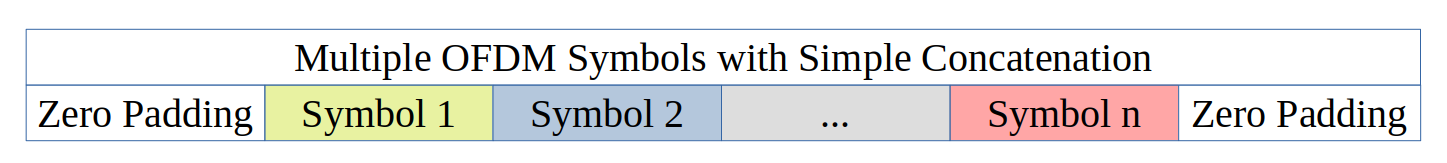

s_upsamp_vec = [zeros(num_carriers*upsamp,1); s_upsamp_vec; zeros(num_carriers*upsamp,1)];
n_upsamp = transpose((1:length(s_upsamp_vec))-num_carriers*upsamp/2-1);
t_upsamp = ts_upsamp * n_upsamp;

    The resulting concatenated signal is plotted in the time domain. Zoom in to view jump discontinuities at the transition times.

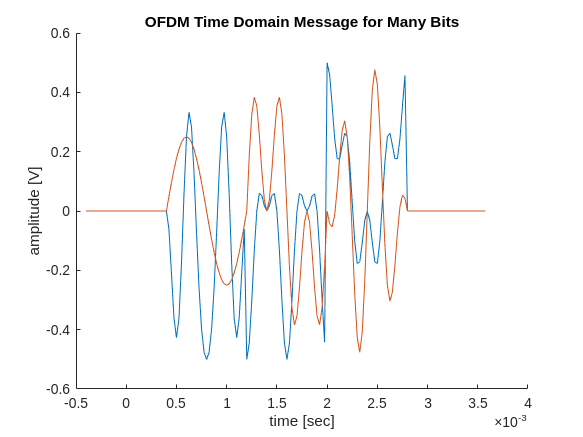

figure(1)
clf
hold on
plot(t_upsamp,real(s_upsamp_vec))
plot(t_upsamp,imag(s_upsamp_vec))
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

    Now, the spectrum of the concatenated message is taken. There are significant high frequency components in this signal which look like the expected response from rectangular windowing. These spectral components would produce out-of-band emissions (spurs) that would make this protocol not conform to wireless channel requirements. 

    One solution to this problem is to much reduce the bandwidth of the message. This means that the spurs would have longer to decay before reaching outside the alloted bandwidth. This is not a great solution because this would greatly reduce the throughput (bit rate) by orders of magnitude. Much of the channel bandwidth would not be used for sending information, but just to let the sidebands decay enough to fit within the channel. A better solution uses filtering to shape the spectrum of the signal to fit in the channel.

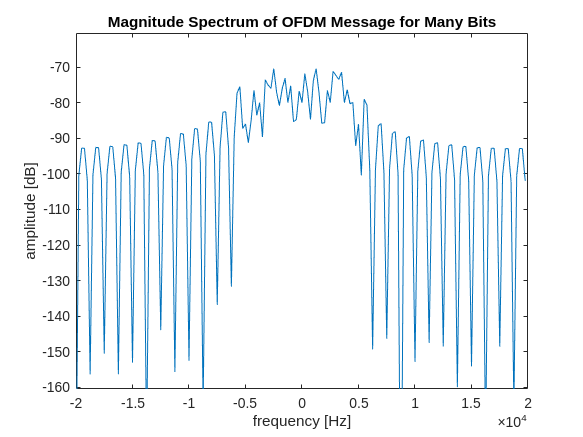

[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_upsamp_vec,fs_upsamp);
mag_spec_upsamp_all = 20*log10(abs(spec_upsamp_all));

figure(2)
clf
plot(f_upsamp_all,mag_spec_upsamp_all)
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

## Filtering to Meet Channel Specifications:

    To filter the message, a few frequency domain parameters are defined. First, a number of guard carriers will be defined to provide space on the outside of the signal for filtering. This is important because of the behavior of filters at the cutoff frequency. Particularly for analog and IIR filters, there will be phase distortion that will impart group delay on the higher frequency components of the signal. This imparts error in decoding the signal even in ideal, noiseless conditions. By including some extra space in the form of "guard carriers" linear phase is preserved. Additionally, for all frequency based filters (analog, IIR, and FIR) there will be some attenuation at the cutoff frequency. By pushing this frequency out a little further, the high frequency carriers are better preserved. See the figure below for a visual representation of guard carriers (or guard sub-carriers).

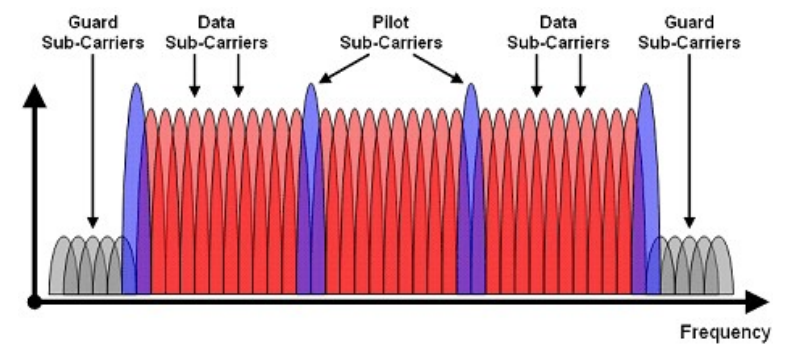

[2] Figure showing a typical frequency domain depiction of OFDM.

    Pick a number of guard carriers below. Try to pick the minimum number that preserves the signal using the frequency domain plot after filtering.

guard_carriers = 2;

    Now, using the guard carriers, the baseband bandwidth of the OFDM message is defined. The data carrying portion of the signal lies within the "useful" bandwidth, which is half of the bandwidth of the passband OFDM signal. The guard bandwidth represents the amount of bandwidth added on each side of the signal to preserve the signal through the filter. Finally, the baseband bandwidth is defined as the sum of the useful and guard bandwidth. This is the bandwidth of the signal passed by the following filter.

bandwidth_useful = bandwidth/2;
bandwidth_guard = guard_carriers/num_carriers*bandwidth/2;
baseband_bandwidth = bandwidth_useful + bandwidth_guard;

    This script uses a digital Butterworth IIR filter because of the minimal distortion in the passband. This is a digital filter which requires a normalized frequency to the nyquist frequency. 

wc = baseband_bandwidth*2/fs_upsamp;

    The IIR filter is designed below.

[b,a] = butter(10,wc);

    MATLAB's filtfilt filtering function is used to filter the signal.This function filters the signal with the FIR taps in the causal and anticausal direction. This removes any delay imparted by filtering so that the filtered and unfiltered signals line up in the following plot.

s_lp = filtfilt(b,a,s_upsamp_vec);

    The filtered and original signals are plotted below. The original signal is plotted in red and the filtered signal is plotted in blue over the red signal. This shows the error imparted on the signal by filtering. Zoom in to view the differences between the filtered and original versions of the signal. These differences will cause bit errors in detection even in the ideal, noiseless case. This is not the optimal solution. Next, a time domain technique called cyclical prefixing will be introduced to solve these differences between the filtered and original signal.

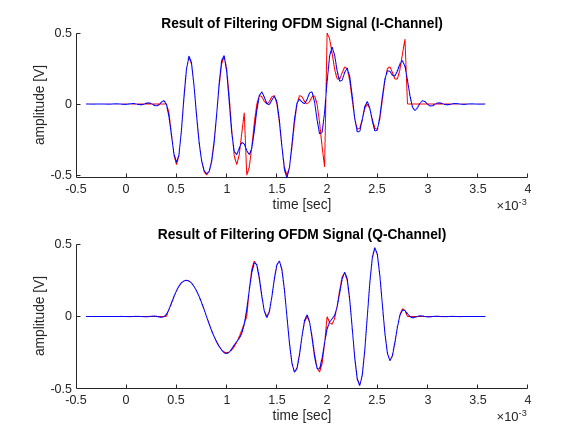

figure(3)
clf
tiledlayout
nexttile
hold on
plot(t_upsamp,real(s_upsamp_vec),'r-')
plot(t_upsamp,real(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_upsamp,imag(s_upsamp_vec),'r-')
plot(t_upsamp,imag(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (Q-Channel)")

    To quantify this error between the filtered and original signal, the mean-square-error (MSE) is calculated. This metric measures the difference between the signals with a low value showing less difference and a high value show high difference. A low value is preferable. The formula for MSE is as follows:

### 
$$MSE = \frac{1}{n} \sum_{i=1}^{n}{|S_i - \hat{S}_i^{^}|^2$$


[3] Formula for calculating the mean-square-error for a complex time series.

[s_upsamp_symbol_length, ~] = size(s_upsamp);
MSE = 1/(s_upsamp_symbol_length*num_symbols) * sum(abs(s_lp(num_carriers*upsamp+1:end - num_carriers*upsamp)-s_upsamp_vec(num_carriers*upsamp+1:end - num_carriers*upsamp)).^2)

MSE = 0.0054

    Next, the spectrum of the filtered and original signals are compared. Again, the original signal is plotted in red and the filtered signal is plotted in blue over the original signal. The filtered signal is confined to a much reduced bandwidth. This is desireable to meet channel specification, but the errors in the time domain present another challenge. Just as some extra bandwidth was added in the frequency domain to provide room for the filter to transition from passband to stopband, an extra time interval can be added between symbols to let the filter track the symbol more effectively. This is called cyclic prefixing.

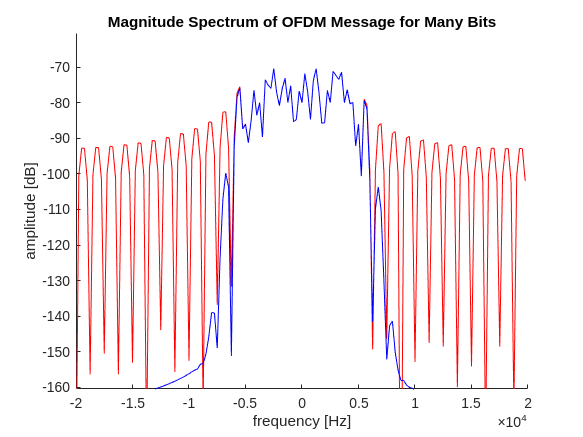

[f_lp, spec_lp] = GetSpectrum(s_lp, fs_upsamp);
mag_spec_lp = 20*log10(abs(spec_lp));

figure(4)
clf
hold on
plot(f_upsamp_all,mag_spec_upsamp_all, 'r-')
plot(f_upsamp_all,mag_spec_lp, 'b-')
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

## Cyclic Prefixing: 

    Cyclic prefixing is a technique widely used in real implementations of OFDM to overcome distortions caused by pulse shaping filters. In essence, cyclic prefixing copies a portion of the end of a symbol to the beginning to allow time for the filter to transit between different OFDM symbols. 

    Why do we copy the end of the symbol to the beginning? Recall that the OFDM symbol is periodic. This means that when the end of the symbol is copied to the beginning, they will line up exactly. This lets the filter have some transition time and nicely flow directly into the important (data containing) part of the transmission. See the figure below for a visual representation of how the end of the OFDM symbol is copied to the beginning. 

    Further, this property can be applied in the opposite direction: copying the beginning of the symbol to the end. In is called cyclic postfixing. In the same way as cyclic prefixing provides a guard interval to transition between symbols, cyclic postfixing provides a guard interval for the end of a symbol. Both cyclic prefixing and postfixing will be used to overcome distortion imparted through filtering.

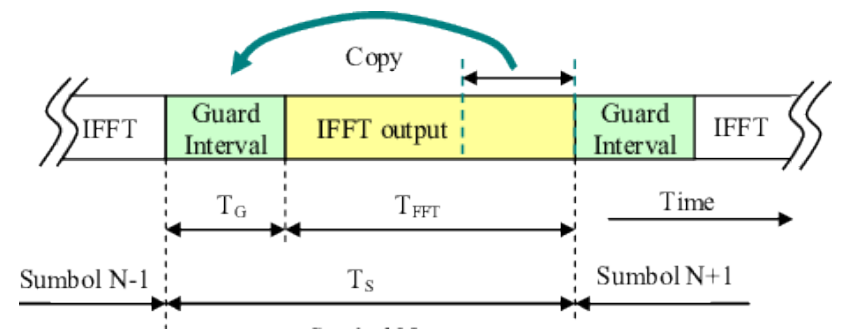

[2] Visual representation of cyclic prefixing.

    Pick a prefix length using the slider below. The prefix length is measured as a fraction of the length of a symbol e.g. a prefix length of 0.5 pads the message with half of the length of the symbol. This value sets the length of the prefix and postfix, so a prefix length value of 0.5 copies half of the message to the front and half of the message to the end, which doubles the length of the time domain message.

prepost_length_percent = 0.5;
prepost_length = round(prepost_length_percent * s_upsamp_symbol_length);
s_p_symbol_length = 2*prepost_length + s_upsamp_symbol_length;

    Next, a simple metric for efficiency is defined by taking the ratio of the prefixed and original form of the message. This is a helpful metric when analyzing tradeoffs regarding the length of the prefix. I.e. a higher prefix length will provide more time for the filter to transit between symbols, but will require more time to send the same information.

efficiency = s_upsamp_symbol_length/s_p_symbol_length;
fprintf("The time domain efficiency of the prefixed/postfixed message is: "); fprintf(num2str(efficiency))

The time domain efficiency of the prefixed/postfixed message is: 0.5

    Now, the prefixed message is generated similar to the figure above. To generate the cyclic prefix, the end of the message (with prefix length defined earlier) will be copied to the beginning of the message. And similarly, the cyclic postfix will be generated by copying the beginning of the message (with postfix length defined earlier) to the end of the message. The format of the output will be an array with each column representing a symbol with included prefix and postfix.

s_prefix_arr = [s_upsamp(end-prepost_length+1:end, :); s_upsamp; s_upsamp(1:prepost_length, :)];

    After this, this array is reshaped into a vector to form a timeseries for the signal and zero padding is applied. Then, the corresponding time vector is generated.

s_prefix = [zeros(num_carriers*upsamp,1); reshape(s_prefix_arr,[],1); zeros(num_carriers*upsamp,1)];

n_prefix = transpose((0:length(s_prefix)-1) - num_carriers*upsamp);
t_prefix = ts_upsamp * n_prefix;

    Again, the baseband signal is filtered with the Butterworth IIR filter using the filtfilt function to remove phase distortion. Then, the I and Q channels are plotted in the figure below. The blue filtered signal is plotted over the red original signal so that distortions caused by filtering can be seen as the red points. There are distortions caused by filtering, but if the prefix and postfix are chosen to be long enough, the distortions in the data timeslot is reduced (and may become negligible).

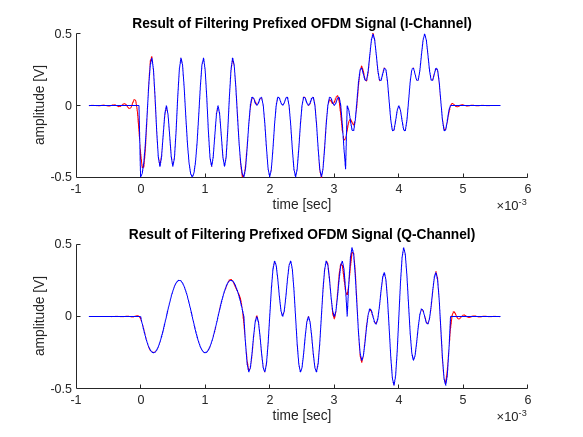

s_prefix_lp = filtfilt(b,a,s_prefix);

figure(5)
clf
tiledlayout
nexttile
hold on
plot(t_prefix,real(s_prefix_lp),'r-')
plot(t_prefix,real(s_prefix),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_prefix,imag(s_prefix_lp),'r-')
plot(t_prefix,imag(s_prefix),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (Q-Channel)")

    Next, the first symbol will be analyzed for the effects of prefixing and postfixing. In the next figure, only the first symbol is shown. The blue portion represents the important timeslot (after filtering) that the receiver will use to recover data, the red still represents the original message, the magenta represents the cyclic prefix and postfix part of the message (that will be thrown out, so distortions are okay). Notice that when a sufficiently long prefix/postfix length is used, the distortion caused by filtering is limited to within the prefix and postfix. The part of the signal in the data timeslot lines up very well and provides minimal distortion.

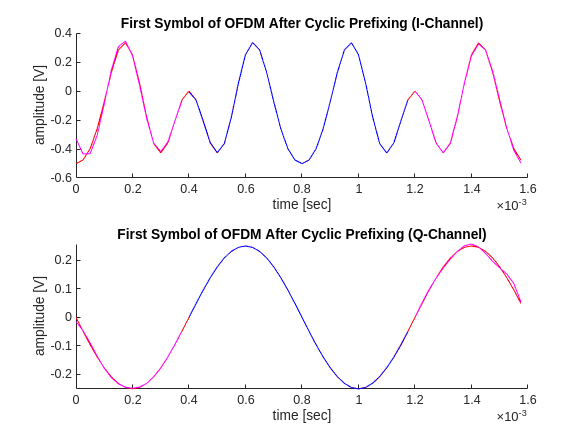

first_symbol_prefix = s_prefix_lp(num_carriers*upsamp+1 : num_carriers*upsamp+prepost_length);
t_first_symbol_prefix = t_prefix(num_carriers*upsamp+1 : num_carriers*upsamp+prepost_length);
first_symbol_data = s_prefix_lp(num_carriers*upsamp+prepost_length+1 : num_carriers*upsamp+prepost_length+s_upsamp_symbol_length);
t_first_symbol_data = t_prefix(num_carriers*upsamp+prepost_length+1 : num_carriers*upsamp+prepost_length+s_upsamp_symbol_length);
first_symbol_postfix = s_prefix_lp(num_carriers*upsamp+prepost_length+s_upsamp_symbol_length+1 : num_carriers*upsamp+2*prepost_length+s_upsamp_symbol_length);
t_first_symbol_postfix = t_prefix(num_carriers*upsamp+prepost_length+s_upsamp_symbol_length+1 : num_carriers*upsamp+2*prepost_length+s_upsamp_symbol_length);
first_symbol_original = s_prefix(num_carriers*upsamp+1 : num_carriers*upsamp+2*prepost_length+s_upsamp_symbol_length);
t_first_symbol_original = t_prefix(num_carriers*upsamp+1 : num_carriers*upsamp+2*prepost_length+s_upsamp_symbol_length);

figure(6)
clf
tiledlayout
nexttile
hold on
plot(t_first_symbol_original, real(first_symbol_original),'r-')
plot(t_first_symbol_prefix, real(first_symbol_prefix),'m-')
plot(t_first_symbol_data, real(first_symbol_data),'b-')
plot(t_first_symbol_postfix, real(first_symbol_postfix),'m-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("First Symbol of OFDM After Cyclic Prefixing (I-Channel)")
nexttile
hold on
plot(t_first_symbol_original, imag(first_symbol_original),'r-')
plot(t_first_symbol_prefix, imag(first_symbol_prefix),'m-')
plot(t_first_symbol_data, imag(first_symbol_data),'b-')
plot(t_first_symbol_postfix, imag(first_symbol_postfix),'m-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("First Symbol of OFDM After Cyclic Prefixing (Q-Channel)")

    Visually, using the cyclic prefixing and postfixing method greatly reduces the distortion caused by filtering. To get a quantitative measurement that proves the effectiveness of this process, the mean-square error (MSE) is recalculated. The below code removes the zero padding and the cyclic prefixing/postfixing portions of the message to keep only the data containing section. This is compared with the original upsampled signal.

s_prefix_lp_arr = reshape(s_prefix_lp(num_carriers*upsamp+1 : end-num_carriers*upsamp),[],num_symbols);
s_prefix_lp_arr = s_prefix_lp_arr(prepost_length+1:end-prepost_length, :);

MSE_prefix = 1/(s_upsamp_symbol_length*num_symbols)*sum(sum(abs(s_prefix_lp_arr-s_upsamp).^2));

    Now, quotient of the original MSE and the MSE after cyclic prefixing is used to get a measurement of how much the error was reduced. When a sufficiently long prefix/postfix is chosen, the error can be reduced by a factor of around 1000. This means that cyclic prefixing/postfixing is effective.

MSE_ratio = MSE/MSE_prefix;
fprintf("There is "); fprintf(num2str(MSE_ratio)); fprintf(" times less error through cyclic prefixing.\n")

There is 828.3771 times less error through cyclic prefixing.


    Finally, the tradeoff between minimizing distortion and maximizing time domain efficiency can be analyzed. Below, a simple product of the MSE ratio and the time domain efficiency is computed. Try to maximize this value by changing the parameters in this script to find the optimal solution!

eff_err_prod = MSE_ratio * efficiency

eff_err_prod = 414.1885

## Summary:

- OFDM signals need to be low-pass filtered to eliminate spurrious emissions to be transmitted over-the-air.

- Low-pass filtering imparts distortion on the signal which corrupts data.

- A technique called Cyclic Prefixing (and/or Cyclic Postfixing) can be used to mitigate filter distortion.

- Cyclic Prefixing copies a portion of the end of the periodic OFDM symbol to the front which gives the filter time to transit between symbols.

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

function bits = RandomBits(num_bits)
    % create a vector of random bits to the required length
    bits = zeros(num_bits,1);
    for i = 1:num_bits
        bits(i) = randi(2,1)-1;
    end
end

## References:

[1] D. Boschen, “How do you visualize the frequency spectrum for a digital waveform?,” *Electrical Engineering Stack Exchange*. https://electronics.stackexchange.com/questions/400275/how-do-you-visualize-the-frequency-spectrum-for-a-digital-waveform

[2] Dr. S. Jacobs, “Unit 8 Lecture 2 - FDM and OFDM,” University of Pittsburgh.

[3] “Mean Square Error - an overview | ScienceDirect Topics,” *www.sciencedirect.com*. https://www.sciencedirect.com/topics/engineering/mean-square-error

‌‌